begin = 1;
ending = 4;
x_raw = rand(1,100);
x = sort(begin+(ending-begin)*x_raw);
fun = @(t) sin(t);


Вычисления:

result_l = left_rectangle(x, fun);
result_m = mid_rectangle(x, fun);
result_tr = trapezoid(x, fun);
result_S = Simpson(x, fun);


Альфы:

for n = 10:1:100
    x_rawtest1 = rand(1,n);
    x_test1 = sort(begin+(ending-begin)*x_raw);
    deviat1 = abs(integral(fun, begin, ending) - left_rectangle(x_test1, fun));
    alph1(n) = -log(deviat1)/log(n);
end

for n = 10:1:100
    x_rawtest2 = rand(1,n);
    x_test2 = sort(begin+(ending-begin)*x_raw);
    deviat2 = abs(integral(fun, begin, ending) - mid_rectangle(x_test2, fun));
    alph2(n) = -log(deviat2)/log(length(x_test2));
end

for n = 10:1:100
    x_rawtest3 = rand(1,n);
    x_test3 = sort(begin+(ending-begin)*x_raw);
    deviat3 = abs(integral(fun, begin, ending) - trapezoid(x_test3, fun));
    alph3(n) = -log(deviat3)/log(length(x_test3));
end

for n = 10:1:100
    x_rawtest4 = rand(1,n);
    x_test4 = sort(begin+(ending-begin)*x_raw);
    deviat4 = abs(integral(fun, begin, ending) - Simpson(x_test4, fun));
    alph4(n) = -log(deviat4)/log(length(x_test4));
end


Графики:

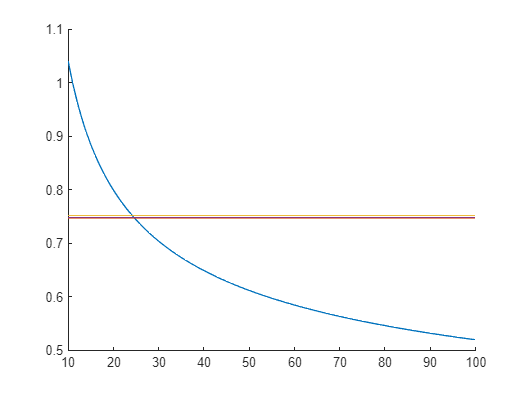

hold on
plot(alph1);
plot(alph2);
plot(alph3);
plot(alph4);
xlim([10 100])